clc, clearvars;

w = warning('off', 'MATLAB:table:ModifiedAndSavedVarnames');
[S, caseName] = creo_xlsx2struct('D:\Creo_Simulations');

t_adh_mm = S.STRESS.t_adh_SIM_STRUCT_SINGLE_LENS_AD;
stress_MPa = S.STRESS.LENS_TOT_STRESS;
shift_um = S.SHIFT.LENS_VERTEX_DISPL;

stress_max_MPa = 36.0;
shift_nom_um = 14.5;

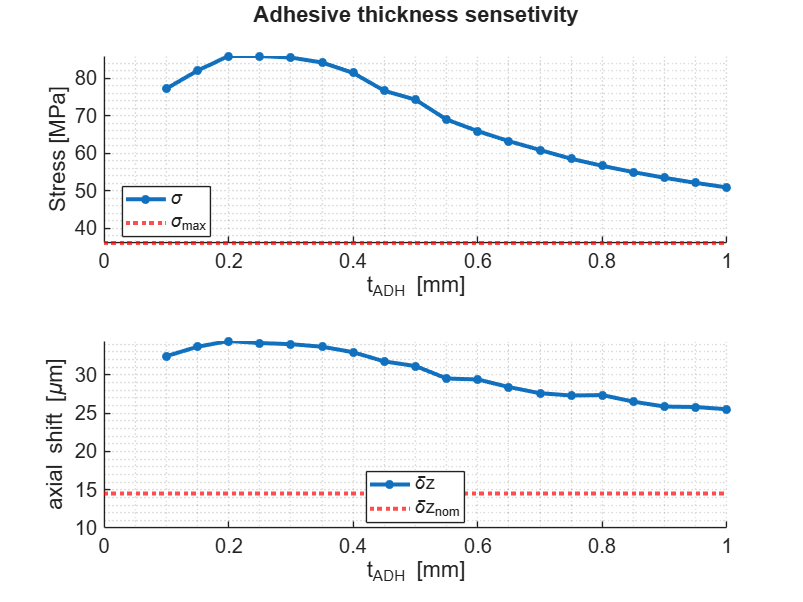

figure('Units','normalized', 'Position',[0 0 0.6 0.8])
ax = [];

ax(1) = subplot(2,1,1);
plot(t_adh_mm,  stress_MPa,'-o' ,...
    'LineWidth', 3.0, 'Marker','.','MarkerSize',20.0,...
    'DisplayName','\sigma');
yline(stress_max_MPa, ':','Color', 'r','LineWidth', 3.0, 'DisplayName','\sigma_{max}')
ylabel('Stress [MPa]');
xlabel('t_{ADH} [mm]');
legend('show', 'Location','best', 'interpreter', 'tex');
title(sprintf('Adhesive thickness sensetivity\n'));
grid minor

ax(2) = subplot(2,1,2);
plot(t_adh_mm, shift_um, '-o',...
    'LineWidth', 3.0, 'Marker','.','MarkerSize',20.0,...
    'DisplayName','\deltaz');
yline(shift_nom_um, ':','Color', 'r','LineWidth', 3.0, 'DisplayName','\deltaz_{nom}')
ylabel('axial shift [\mum]', 'Interpreter','tex');
xlabel('t_{ADH} [mm]');
legend('show', 'Location','best', 'interpreter', 'tex');
grid minor

set(ax, 'Fontsize', 15)
set(ax, 'Box', 'off')